# Deterministic Dynamic Models

We will use the CompEcon Toolbox solvers:

- ddpsolve()    -   Solves discrete-state/action dynamic program

- dpsolve()       -   Solves discrete time Bellman equation

clc;
clear;
close all;

## Example 1: Mine Management

### Problem Statement:

A mine operator must decide how much ore to extract from a mine that will be shut down and abandoned after T years of operation. The price of extracted ore is p dollars per ton, and the total cost of extracting x tons of ore in any year, given that the mine contains s tons at the beginning of the year, is $\frac{x^2}{1+s}$. The mine currently contains $\bar s$ tons of ore. 

Determine the extraction schedule that maximizes the present value of the mine's profit stream.

### Solution:

% DEMDDP01 Mine Management Model
clc;
clear;
fprintf('\nDEMDDP01 MINE MANAGEMENT MODEL\n')


DEMDDP01 MINE MANAGEMENT MODEL


close all;

Consider the mine management model with market price $p=1$, initial stock of ore $\bar s=100$, and annual discount factor $\delta=0.90$.

The first step required to solve the model numerically is to specify the model parameters and to construct the state and action spaces:

% Enter model parameters
  price = 1;                    % price of ore
  sbar  = 100;                  % initial ore stock
  delta = 0.9;                  % discount factor  

% Construct state and action spaces
  S = (0:sbar)';                % vector of states
  X = (0:sbar)';                % vector of actions
  n = length(S);                % number of states
  m = length(X);                % number of actions


Next we need to construct the transition probability matricies:

% Construct reward function (f) and state transition function (g)

% Non-vectorized version

if 1 % if 1 then non-Vectorized; otherwise Vectorized
    
  f = zeros(n,m); % reward matrix
  for i=1:n
  for k=1:m
    if X(k)<=S(i)
      f(i,k) = price*X(k)-(X(k)^2)./(1+S(i));
    else
      f(i,k) = -inf;
    end
  end
  end
  
  g = zeros(n,m); %transition matrix
  
  for i=1:n
  for k=1:m
    snext = S(i)-X(k);
    g(i,k) = getindex(snext,S);
  end
  end
  
fprintf('USING..........non-Vectorized version of code \n')  
  
% Vectorized version
else
    
  [SS,XX] = gridmake(S,X);
  f = (price-XX./(1+SS)).*XX;
  f(XX>SS) = -inf;
  f = reshape(f,n,m);
  g = getindex(SS-XX,SS);
  g = reshape(g,n,m);
  clear SS XX
  
  fprintf('USING..........Vectorized version of code \n')
end

USING..........non-Vectorized version of code 


Notice that a reward matrix element is set to negative infinity if the extraction level exceeds the available stock. This guarantees that the value maximization algorithm will not chose an infeasible action. Also, note that we have defined the deterministic state transition rule $g$.

We now need to pack the essential data into the structured variable $model$.

% Pack model data
  clear model
  model.reward     = f;
  model.transfunc  = g;
  model.discount   = delta;
  model.horizon    = inf;
  

To solve the infinite horizon model via policy iteration, we simply type the following:

% Solve model using policy iteration
  [v,x,pstar] = ddpsolve(model);

Solve Bellman equation via Newton method
    1    2.7e+02
    2    6.2e+01
    3    6.3e+00
    4    1.1e+00
    5    3.6e-01
    6    1.7e-01
    7    4.0e-02
    8    3.3e-03
    9    0.0e+00


We can also solve the infinite horizon model via function iteration by:

% Solve model using function iteration
%  [v,x,pstar] = ddpsolve(model, 'func');

After convergence, the $v$ contains the value function and $x$ will be the vector of indices of the optimal ore extractions. Note that the policy iteration algorithm was not explicitly specified because it is the default algorithm when the horizon is infinite.

If we wanted to solve the problem over a ten year horizon we simply do the following:

  model.horizon = 10;
  [v_finite, x_finite, pstar_finite] = ddpsolve(model);

Solve Bellman equation via backward recursion


The backward recursion algorithm was not explicitly specified because it is the default algorithm when the horizon is finite. We see that x_finite is an nx10 matrix containing the optimal ore extraction policy for all possible ore stock levels for period 1 to 10. The columns of x represent periods and its rows represent states. Similarly, v_finite is an nx11 matrix containing the optimal values for all possible stock levels for periods 1 to 11.

The CompEcon toolbox provides a utility for performing dynamic analysis. The algorithm, ddpsimlu() is employed as follows:

st=ddpsimul(pstar, s1, nyrs, x)

The inputs are, pstar which is the optimal probability transition matrix induced by the optimal policy; x is the optimal policy; s1 is a kx1 vector of initial states, each entry of which initiates a distinct replication of the optimized state process; and nyrs is the number of years for which the process will be simulated. Type 'help ddpsimul' in the Command Window  to get more details about this function.

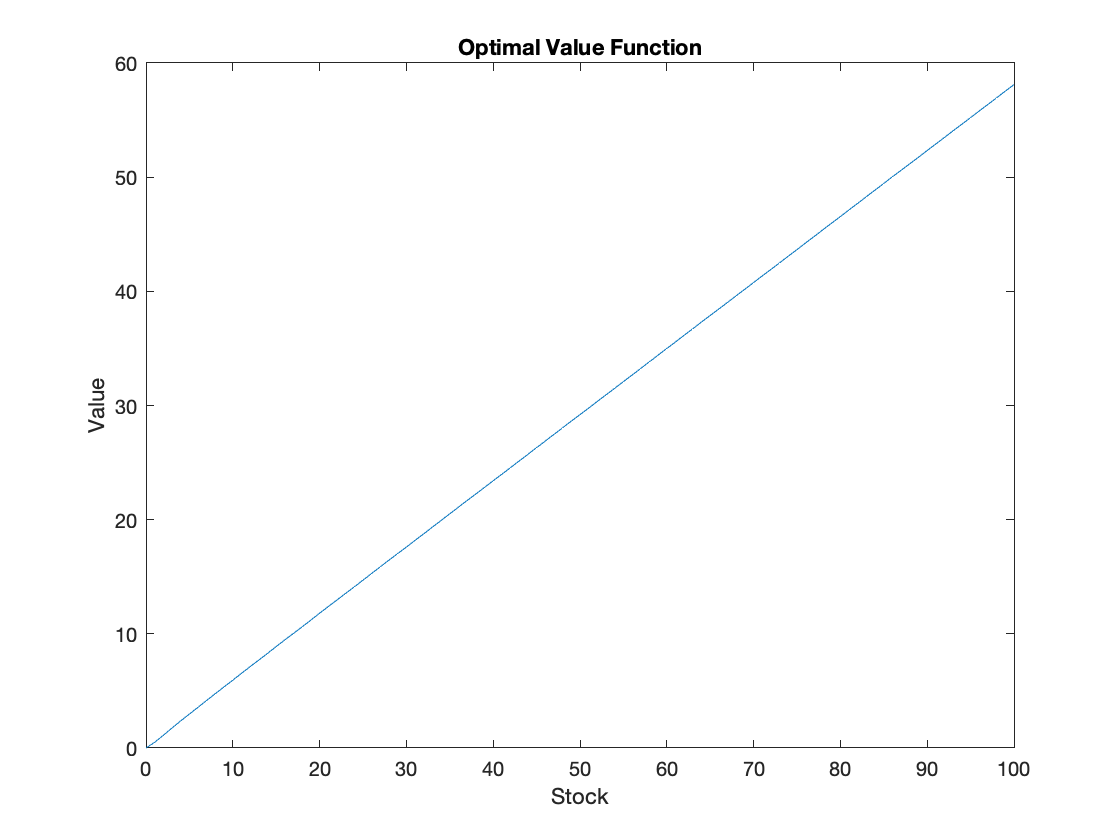

%%%%% Plots %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
  
% Plot optimal value function
  figure(1); plot(S,v);
  title('Optimal Value Function');
  xlabel('Stock'); ylabel('Value');

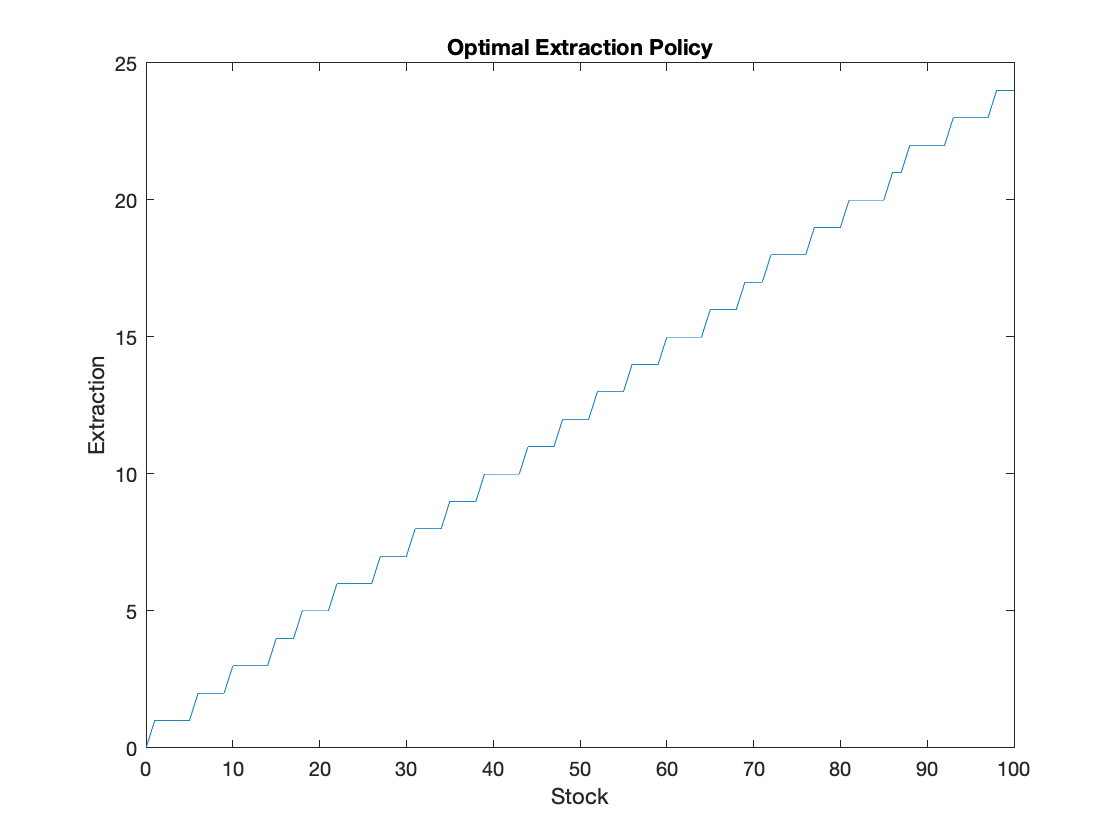


% Plot optimal policy function
  figure(2); plot(S,X(x)); 
  title('Optimal Extraction Policy');
  xlabel('Stock'); ylabel('Extraction');

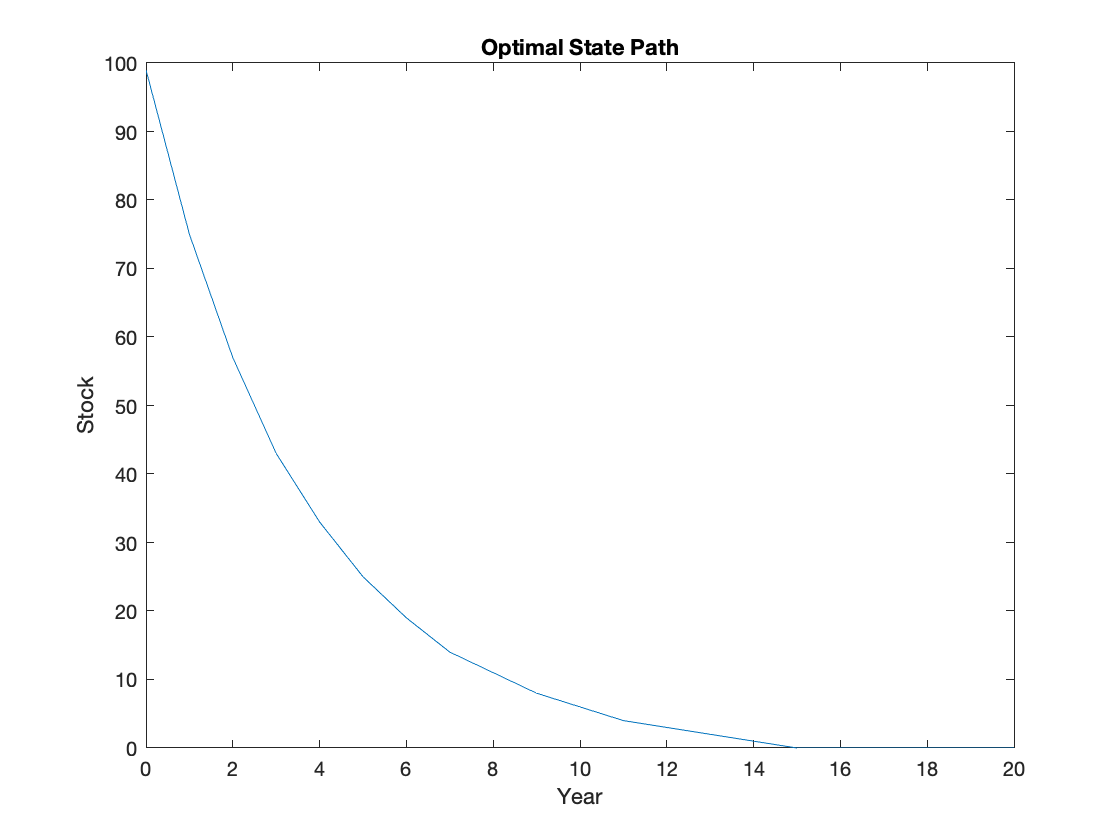


% Generate optimal path
  sinit = max(S); nyrs = 20;
  spath = ddpsimul(pstar,sinit,nyrs);

% Plot optimal path
  figure(3); plot(0:nyrs,S(spath));
  title('Optimal State Path');
  xlabel('Year'); ylabel('Stock');

### In Lab Exercise:

Modify the above script to conduct a sensitivity analysis in terms of the price of ore. Determine how an increase in the ore price will change the optimal extraction policy, the value of the mine, and the lifetime of the mine. Create plots to show this change over the range of the ore price.

### **ddpsolve  **

### **Solves discrete-state/action dynamic program**

  USAGE

    [v,x,pstar] = ddpsolve(model,v);

  INPUTS

    model   : model structure variable (see below)

    v       : initial guess for value function (optional)

  OUTPUTS

    v       : value function (nx1 or nxT+1)

    x       : optimal controls (nx1 or nxT)

    pstar   : optimal transition probability matrix (nxn or nxnxT+1)

**  The possible fields of the model structure variable are:**

    discount  : a scalar on (0,1]

    reward    : nxm matrix of reward values

    transfunc : for deterministic problems 

                   an nxm matrix of values on {1,...,m}

    transprob : for stochastic problems

                   mxnxn a set of m nxn probability matrices

    T         : number of time periods 

                   (omit or set to inf for infinite horizon problems)

    vterm     : terminal (time T+1) value function

  discount and reward must be specified. Either transfunc or transprob must

  be specified. 

  If T is omitted, an infinite horizon problem is assumed. 

  If vterm is omitted, the terminal value if assumed to be 0.

  USER OPTIONS (SET WITH OPSET)

    tol       : convergence tolerance

    maxit     : maximum number of iterations

    prtiters  : 0/1 print each iteration

    algorithm : 'newton' or 'funcit' 

                for infinite horizon problems (default: 'newton')

### **ddpsimul  **

### **Monte Carlo simulation of discrete-state/action controlled Markov process**

  USAGE

    spath = ddpsimul(pstar,s,N,x)

  INPUTS

    pstar   : optimal state transition matrix

    s       : k by 1 vector of initial states

    N       : number of simulated time periods

    x       : optimal controls

  OUTPUT

    spath   : k by N+1 vector of simulated states

## Example 2: Livestock Feeding Model

### Problem Statement:

A livestock producer feeds his stock up to period $T$ and then sells it at the beginning of period $T+1$ at a fixed $p$ per unit weight. Each period, the producer must determine how much grain $x$ to feed his livestock, given that grain sells at a constant unit cost $k$. The weight of the livestock is governed by the state transition function $s_{t+1}=g(s_t , x_t)= \alpha s_t+x_t^{\beta}$.

What feeding policy maximizes profits, given that the livestock weights $\bar s$ in period 0?

General Notes:

- A producer feeds his livestock for $T$ periods and then sells it at the beginning of period $T+1$ at a contractually fixed price of $p$ dollars per unit weight.

- At the beginning of period t, the producer must decide how much weight $x_t$ his livestock should gain.

- A quantity of feed $g(s_t , x_t)$ is required to increase livestock weight by $x_t$ units if it currently weighs $s_t$ units.

- The cost of feed is k dollars per unit.

- The livestock weighs $s_1$ units when initially acquired.

**Formulation**

This is a finite-horizon, deterministic model with the following structural features:

- One continuous state variable, livestock weight $s_t\in[0,\infty]$

- One continuous action variable, livestock weight gain $x_t\in[0,\infty]$

The reward is current profit: $\[\pi  = \left\{ {\begin{array}{*{20}{c}}
{ - kg({s_t},{x_t}),}\\
{p{s_{t + 1}},}
\end{array}\begin{array}{*{20}{c}}
{t \le T}\\
{t = T + 1}
\end{array}} \right.\]$

State transitions are governed by $s_{t+1}=s_t+x_t$

**Bellman Equation**

The value of livestock that weighs s at time t, satisfies theBellman equation,


$$\[{V_t}(s) = \mathop {\max }\limits_{x \ge 0} \{  - kg(s,x) + \delta {V_{t + 1}}(s + x)\} \]$$


$t=1,2,...,T$, subject to the terminal condition $V_{T+1}(s)=ps$

**Euler Conditions**

The shadow price of livestock weight in period t, $\lambda_t(s)$, given its weight is s, satisfies the Euler conditions


$$$$



$$0=-kg_x(s,x)+\delta \lambda_{t+1}(s+x)
$$



$$\lambda_t(s)=-kg_s(s,x)+\delta \lambda_{t+1}(s+x)$$


$t=1,2,...,T$, subject to the terminal condition $\lambda_{T+1}=p$

**Numerical Solution**

- Because the model is deterministic and has finite horizon, it is not necessary to solve the Bellman equation.

- Instead, we can directly solve the Euler conditions as a complementarity problem for weight levels $s_1, s_2, ...,s_{T+1}$ and shadow prices$\lambda_1,\lambda_2,...,\lambda_{T+1}$.

- The Bellman equation, however, may be solved using collocation, if desired. This is what we will do here.

- The collocation method calls for the value functions to be approximated using linear combinations of $n$ judiciously chosen basis functions $\phi_j$:

            
$$\[{V_t}(s) \approx \sum\limits_{j = 1}^n {{c_{jt}}{\phi _j}(s)} \]$$


            $t=1,2,...,T$.

- The $Txn$ coefficients $c_{jt}$ are fixed by requiring the value function approximants to satisfy the $T$ Bellman equations at $n$ judiciously chosen nodes $s_i$.

- This requires solving the $Txn$ nonlinear collocation equations:

            
$$\[\sum\limits_{j = 1}^n {{c_{jt}}{\phi _j}({s_i}) = \mathop {\max }\limits_{x \ge 0} \{  - kg({s_i},x) + \delta \sum\limits_{j = 1}^n {{c_{(t + 1,j)}}\phi ({s_j} + x)} \} } \]$$


            
$$t=1,2,...,T-1$$


            
$$\[\sum\limits_{j = 1}^n {{c_{Tt}}{\phi _j}({s_i}) = \mathop {\max }\limits_{x \ge 0} \{  - kg({s_i},x) + \delta p({s_i} + x)\} } \]$$


            $i=1,2,...,n$, for the $T x n$ unknown coefficients $c_{tj}$,

            $t=1,2,...,T\quad and \quad j=1,2,...,n$.

### Solution:

The model can be solved in two ways:

First, the Euler conditions can be solved directly using broyden.

Second, the Bellman equation can be solved via collocation using dpsolve(), with the value function approximated by a linear combination of n = 50 cubic spline basis functions on [0.4, 4.0].

**Note: **If you want to learn more more about Broyden's Method and the collocation method please reference the textbook. Depending on the version of the book, see section 3.4 - Quasi-Newton Method for Broyden's Method and section 9.2 - The Collocation Method. You can also navigate to the course lab website, launch the Python Binder, go to the Optim_Class folder, then the PythonFns folder. You will find a Jupypter notebook called DEMAPP09_Cournot_oligopolist_problem. This notebook contains an example on how to solve the Cournot Oligopoly Model using the Broyden and Collocation Methods.

Problem Parameters:


$$g(s,x)=(x+\alpha s)^\beta$$



$$\alpha=0.9$$



$$\beta=0.5$$



$$s_1=0.4$$



$$k=0.4$$



$$p=1$$



$$T=6$$



$$\delta=0.9$$


  % DEMDP14 Livestock Feeding Model
clc;
clear;
close all; 
  fprintf('\nDEMDP14 LIVESTOCK FEEDING MODEL\n')


DEMDP14 LIVESTOCK FEEDING MODEL


% ENTER MODEL PARAMETERS
  alpha =  0.9;                                         % growth function parameter
  beta  =  0.5;                                         % growth function parameter
  kappa =  0.4;                                         % unit cost of feed
  price =  1.0;                                         % unit price of stock
  T     =  6;                                           % time horizon
  delta =  0.9;                                         % discount factor
  
% PACK MODEL STRUCTURE
  clear model
  model.func = 'mfdp14';                                % model functions
  model.horizon = T;                                    % time horizon
  model.discount = delta;                               % discount factor
  model.params = {alpha beta kappa};                    % other parameters
  
% DEFINE APPROXIMATION SPACE
  n    = 50;                                            % degree of approximation
  smin = 0.4;                                           % minimum state   
  smax = 2.0;                                           % maximum state
  fspace = fundefn('spli',n,smin,smax);                 % function space
  snodes = funnode(fspace);                             % state collocaton nodes
  
% CHECK MODEL DERIVATIVES
  dpcheck(model,(smax+smin)/2,1);

% INITIALIZE POLICY, VALUE, PRICE FUNCTIONS
  xinit = ones(n,1);                                    % guess for terminal policy function
  vterm = price*snodes;                                 % post-terminal value function
  
% SOLVE BELLMAN OR EULER EQUATION
  [c,s,v,x] = dpsolve(model,fspace,snodes,vterm,xinit);

Solving for time 6
Solving for time 5
Solving for time 4
Solving for time 3
Solving for time 2
Solving for time 1


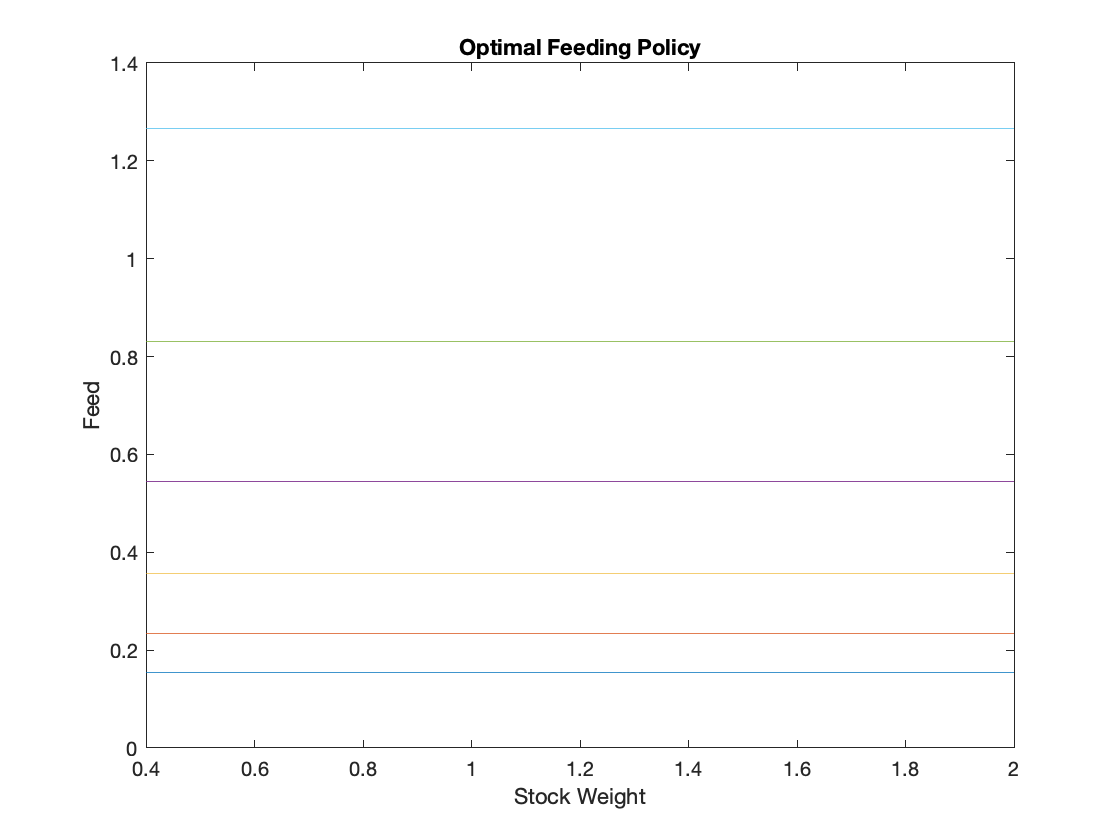

  
  
  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
  %%%%% Plotting
  
  
  % PLOT OPTIMAL POLICY
  figure(1);
  plot(s,x(:,1:T)); % added x(:,1:T) to eliminate dim error
  %plot(s,x)
  title('Optimal Feeding Policy');
  xlabel('Stock Weight');
  ylabel('Feed');

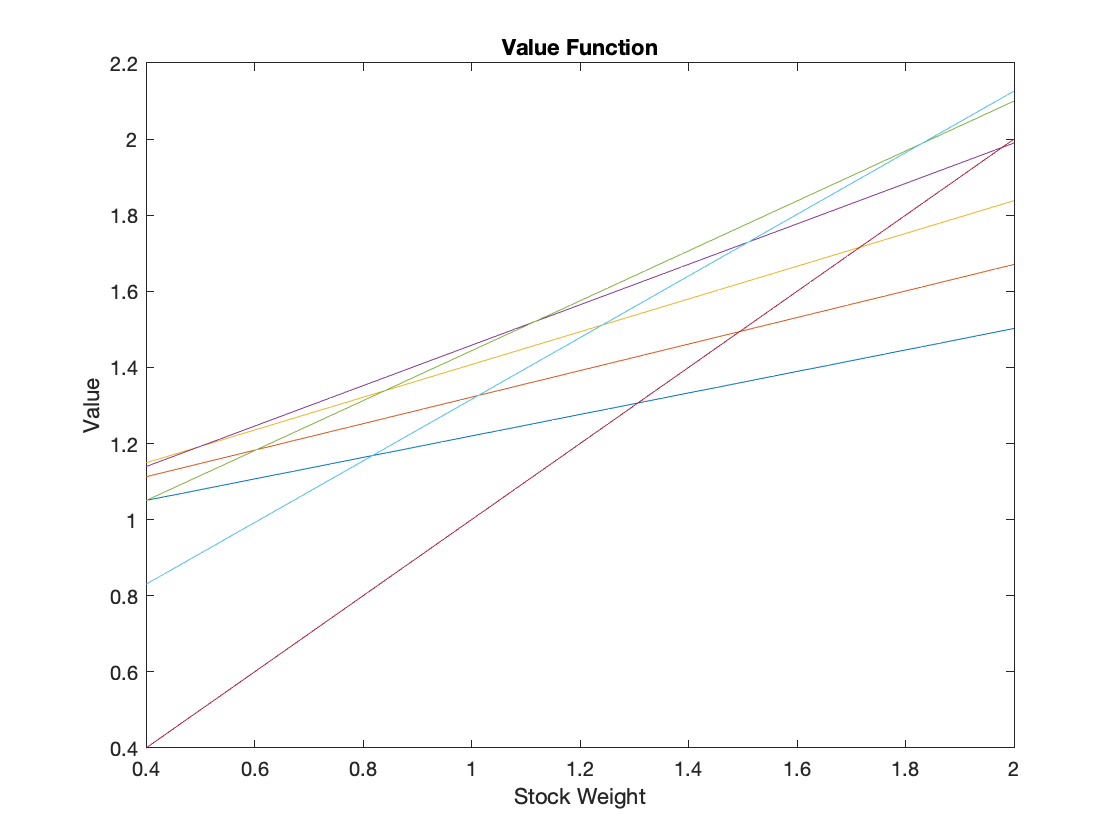

%   
% % PLOT OPTIMAL POLICY Added plots
%   x_reshape = reshape(x, [50,T]); % added to eliminate dim error
%   hFig = figure(2);
%   set(hFig, 'Position', [100 100 1400 800])
%   figure(2);
%   for i = 1:T % added to plot all time periods
%   subplot(2,3,i);
%   plot(s, x(:,i));
%   title('Optimal Feeding Policy');
%   xlabel('Stock Weight');
%   ylabel('Feed');
%   legend(sprintf('time horizon=%d',i), 'location', 'NorthWest')
%   end
  
  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% PLOT VALUE FUNCTION
  figure(3);
  plot(s,v)
  title('Value Function');
  xlabel('Stock Weight');
  ylabel('Value');

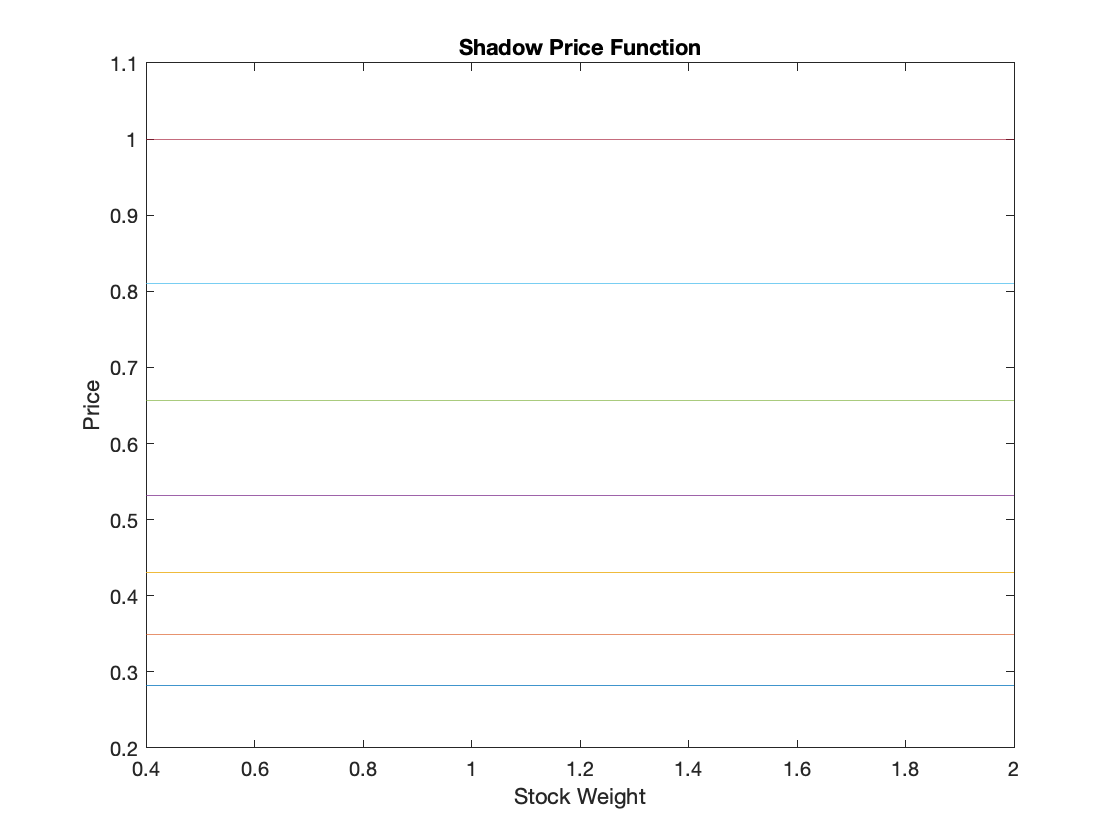


% PLOT SHADOW PRICE FUNCTION
  figure(4);
  p = funeval(c,fspace,s,1); 
  plot(s,p);
  title('Shadow Price Function');
  xlabel('Stock Weight');
  ylabel('Price');

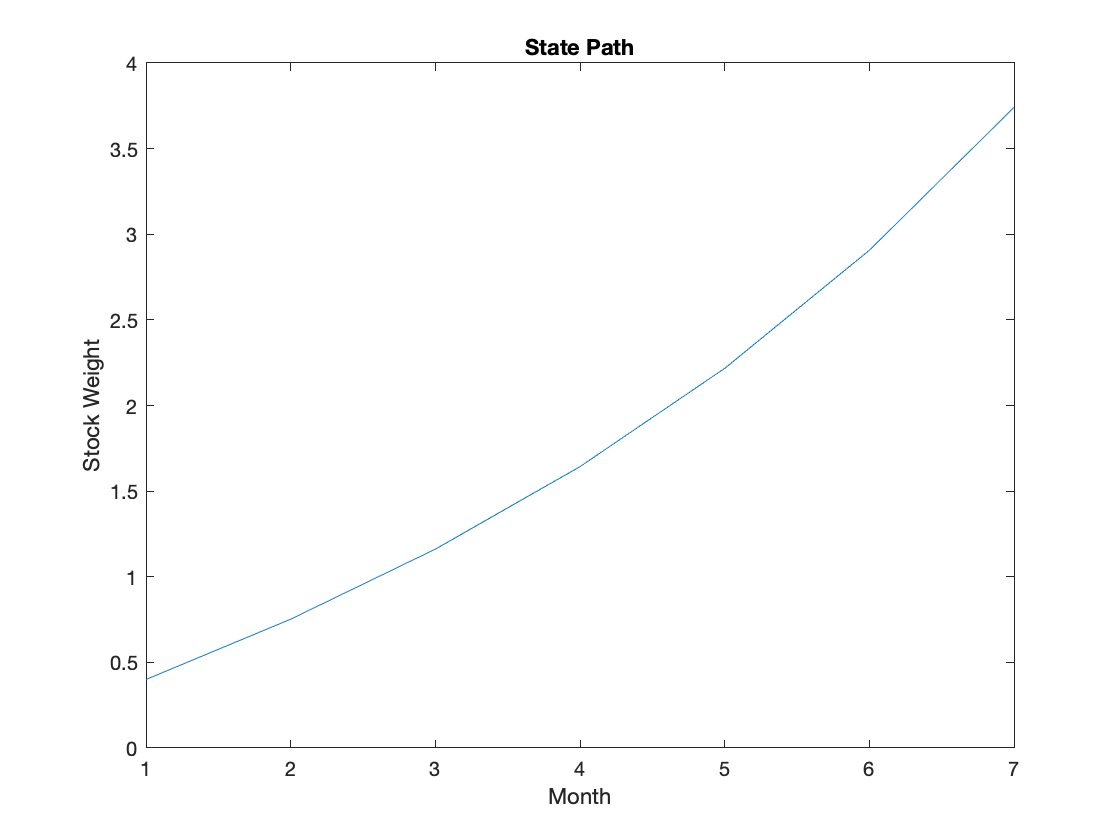


% COMPUTE STATE AND POLICY PATH
  sinit = smin;
  [spath,xpath] = dpsimul(model,sinit,T,s,x);
  
% PLOT STATE PATH
  figure(5);
  plot(1:T+1,spath);
  title('State Path');
  xlabel('Month');
  ylabel('Stock Weight');
  xlim([1 7])

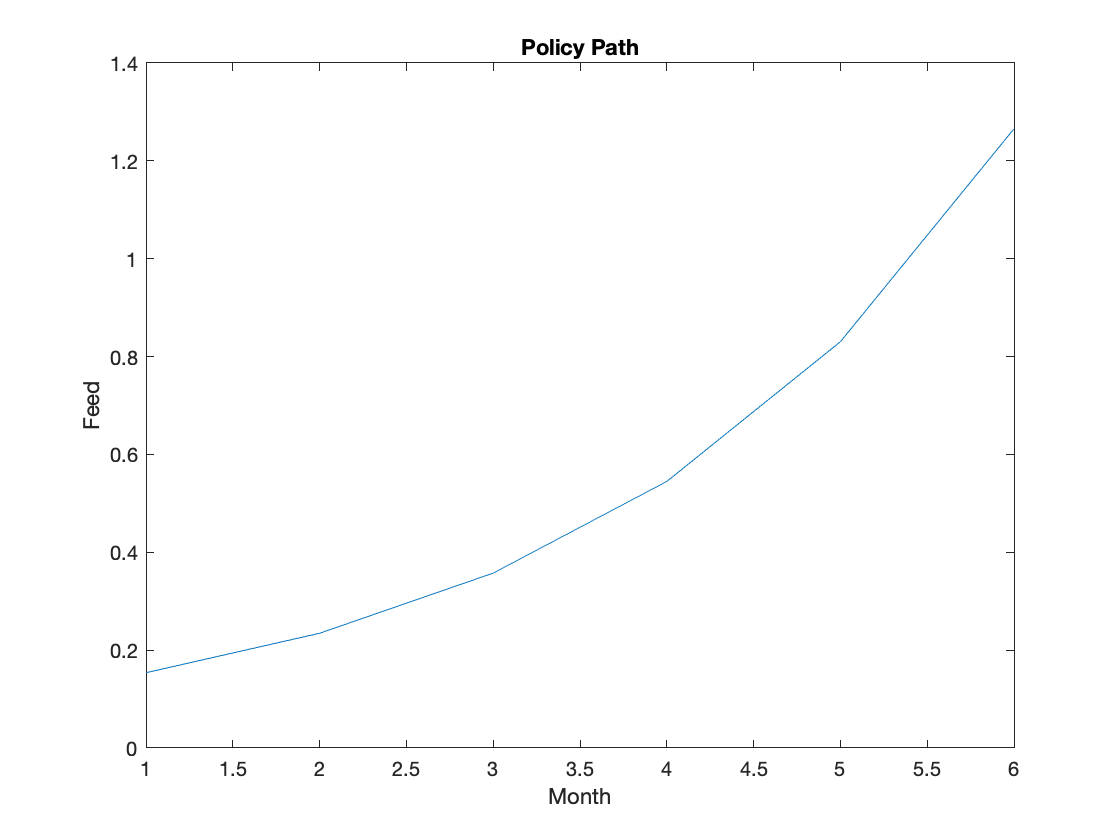

  
% PLOT POLICY PATH
  figure(6);
  plot(1:T,xpath);
  title('Policy Path');
  xlabel('Month');
  ylabel('Feed');

### In Lab Exercise:

The terminal livestock weight is 3.7407 (given by 'spath')

How does the value function change if...

- original conditions hold except, unit cost of feed increases to 0.5?

- original conditions hold except, market prices increase 20%?

- original conditions hold except, interest rate increases, so that $\delta=0.85$?

### **dpsolve  **

### **Solves discrete time  Bellman equation**

  USAGE

    [c,scoord,v,x,resid] = dpsolve(model,fspace,s,v,x);

  INPUTS

    model     : dynamic program model structure

    fspace    : name of projection space structure

    s         : matrix of state nodal values

    v         : initial guess for values or shadow prices at nodes

    x         : initial guess for optimal continuous actions at nodes

  OUTPUTS

    c         : value function approximation basis coefficients

    scoord    : residual evaluation coordinates (cell array for ds>1)

    v         : value function at evaluation points

    x         : optimal action at evaluation points

    resid     : Bellman equation residuals at evaluation points

  MODEL STRUCTURE FIELDS

    func           : function file name (see below)

    discount       : discount factor

    e              : shocks

    w              : probabilities    

    horizon        : an integer or inf

    actions        : vector or cell array of discrete actions

    discretestates : vector of indices of discrete states

    params         : additional parameters to function file

  FUNCTION FILE FORMAT

    [out1,out2,out3] = func(flag,s,x,e,additional parameters)

    if flag = 'b' returns bound function

       xl:ns.dx, xu:ns.dx

    if flag = 'f' returns reward function and derivatives

       f:ns.1, fx:ns.dx, fxx:ns.dx.dx

    if flag = 'g' returns transition function and derivatives

       g:ns.ds, gx:ns.ds.dx, gxx:ns.ds.dx.dx

    where ns = number of collocation states 

          ds = state space dimension

          dx = action space dimension

  USER OPTIONS (SET WITH OPSET)

    tol       : convergence tolerance

    maxit     : maximum number of iterations

    nres      : nres*fspace.n uniform nodes to evaluate residual

    showiters : 0/1, 1 to display iteration results

    algorithm : 'newton' (the default) or 'funcit'

  USER OPTIONS FOR DPSOLVE_VMAX

    tol          : convergence tolerance used by CP solver (default: 5e-8);

    maxit        : maximum number of iterations used by CP solver (default: 50)

    maxbacksteps : maximum number of backsteps used by CP solver (default: 0)

    lcpmethod    : 'minmax' (the default) or 'smooth'

  Note: actions must be either all discrete or all continuous (states can be mixed)

### ** fundefn **

### **Defines a function family structure**

  USAGE

    fspace = fundefn(bastype,n,a,b,order,s1,s2,...);

  INPUTS

    bastype  : the string referencing function family ('cheb','spli' or 'lin')

    n        : order of approximation along each dimension

    a        : left endpoints of interpolation intervals in each dimension

    b        : right endpoints of interpolation intervals in each dimension

    order    : for 'spli' bastype, the order of the spline (default: 3 for cubic)

    s1,s2... : additional column vectors for appending discrete variables to

                 the basis

  OUTPUT

    fspace  : a function family structure

  USES: fundef

  See also: fundef, funeval, funbas.